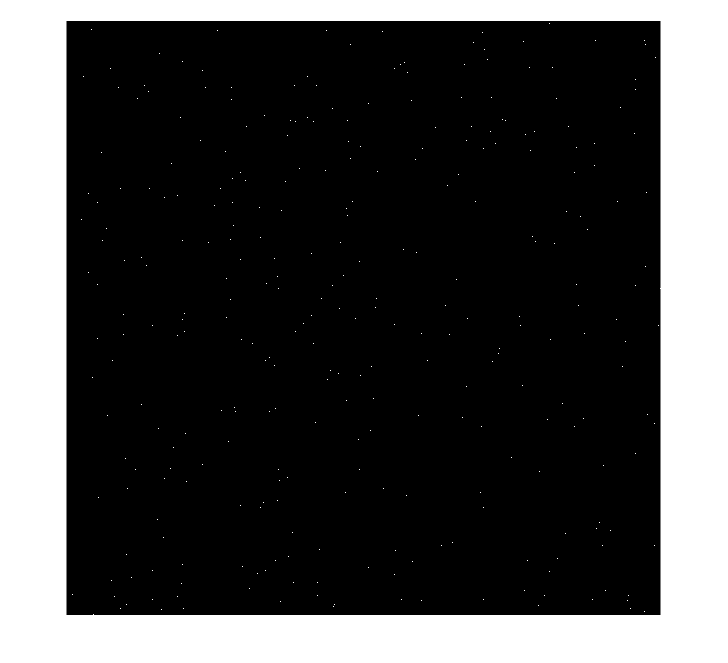

% 生成随机点
clc;clf;
L=800;
fwPic=imnoise(zeros(L),'gaussian',0,0.1);
fwPic(fwPic<0.996)=0;
imshow(fwPic)

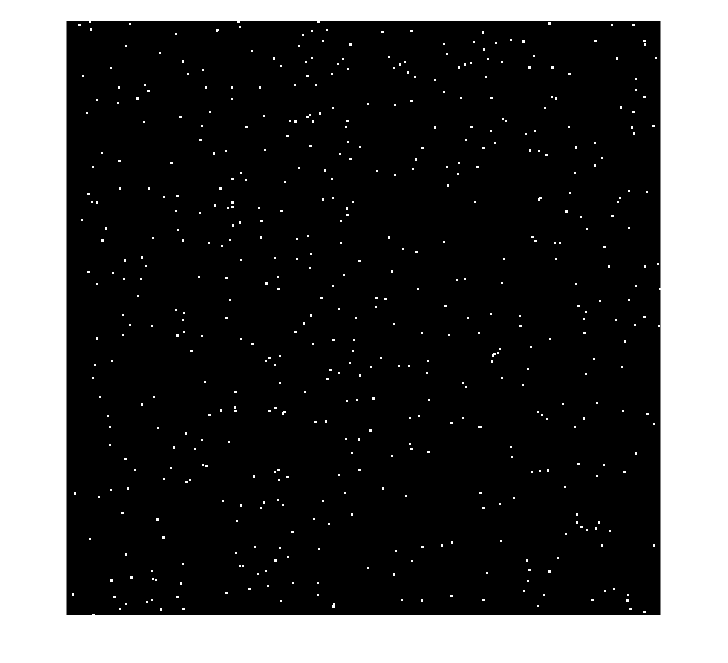

% 图形学膨胀
clc;clf;
fwPic=imdilate(fwPic,strel('square',3));
imshow(fwPic)

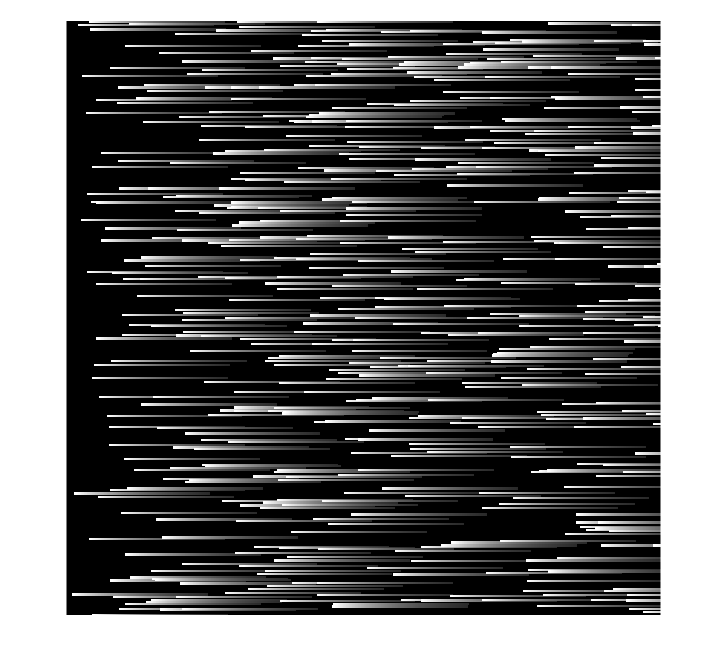


% 特效[风]
clc;clf;
for i=1:180
    tPic=[zeros(L,1),fwPic(:,1:end-1)].*.99;
    fwPic(fwPic<tPic)=tPic(fwPic<tPic); 
end
imshow(fwPic)

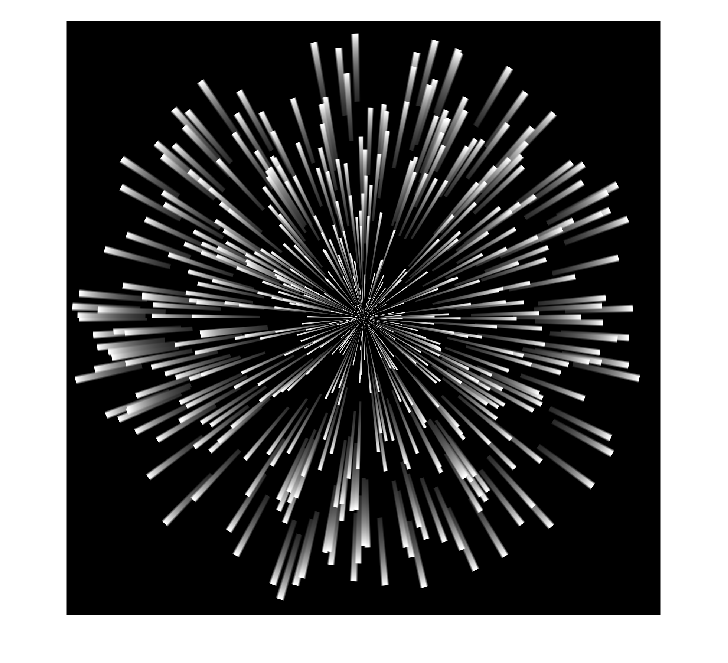


% 极坐标变换
clc;clf;
[t,r]=meshgrid(linspace(-pi,pi,L),L:-1:1);
[X,Y]=meshgrid((1:2*L)-L-.5);
[T,R]=cart2pol(X,Y);
fwPic=interp2(t,r,fwPic',T,R,'linear',0);
imshow(fwPic)

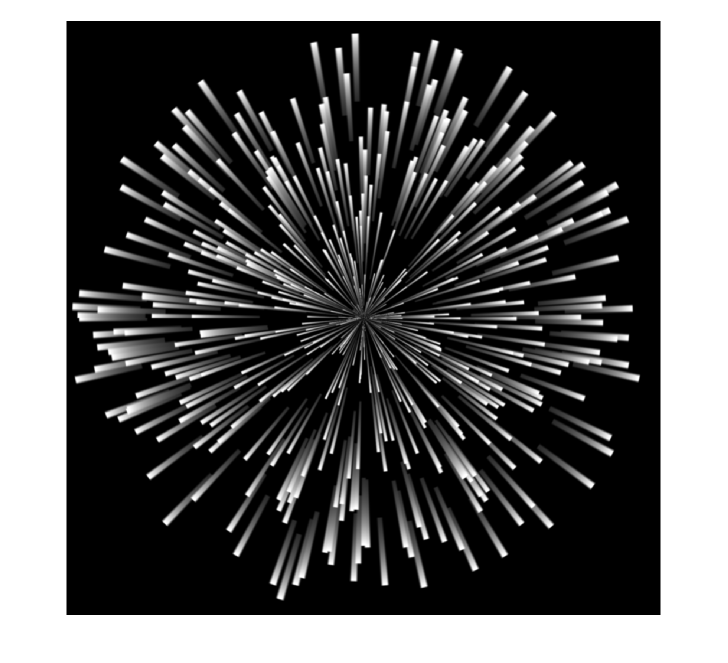


% 中心模糊
clc;clf;
fwPic=imgaussfilt(fwPic,1.5);
fwPic=fwPic./max(max(fwPic)).*1.02;
imshow(fwPic)

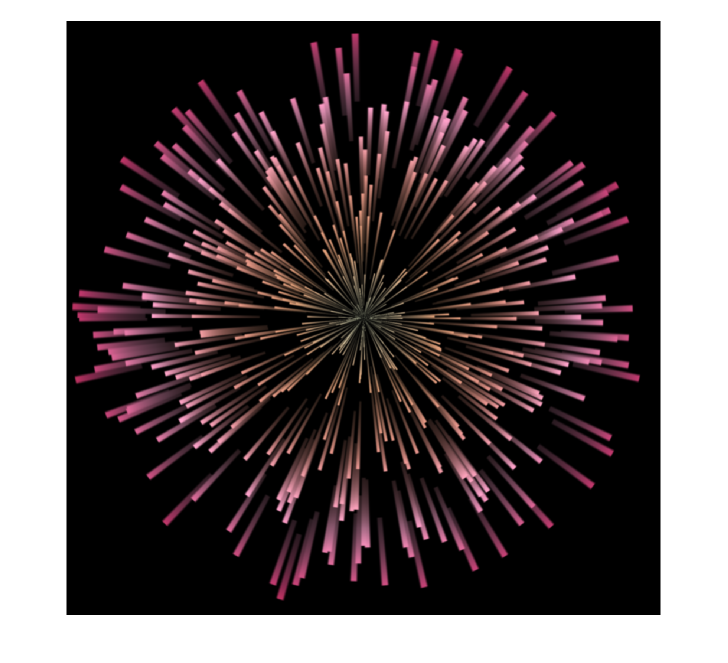


% 图像上色
clc;clf;
CList=[239,250,210
       229,164,122
       232,150,138
       255,164,204
       192,58 ,111
       158,10 ,26
       224,168,121];
% CList=bone().*255;
% CList=pink().*255;
% CList=winter().*255;
CNum=size(CList,1);
tList=linspace(0,1,CNum);
RMat=R./max(max(R));
rPic=interp1(tList,CList(:,1),RMat).*fwPic;
gPic=interp1(tList,CList(:,2),RMat).*fwPic;
bPic=interp1(tList,CList(:,3),RMat).*fwPic;
fwPic=uint8(cat(3,rPic,gPic,bPic));
imshow(fwPic)